1

x = [0 2 4 6 9 11 12 15 17 19];
y = [5 6 7 6 9 8 8 10 12 12];
x_summation = Summation(x);
y_summation = Summation(y);
xy_summation = xySummation(x,y);
xSqu_summation = xsquSummation(x);
ySqu_summation = xsquSummation(y)

ySqu_summation =    743


x_square_summation = 0;
n=length(x);


[slope,intercept] = least_square(x_summation,y_summation,xy_summation,xSqu_summation,n)

slope =    0.359145527369826


intercept =    4.888117489986650


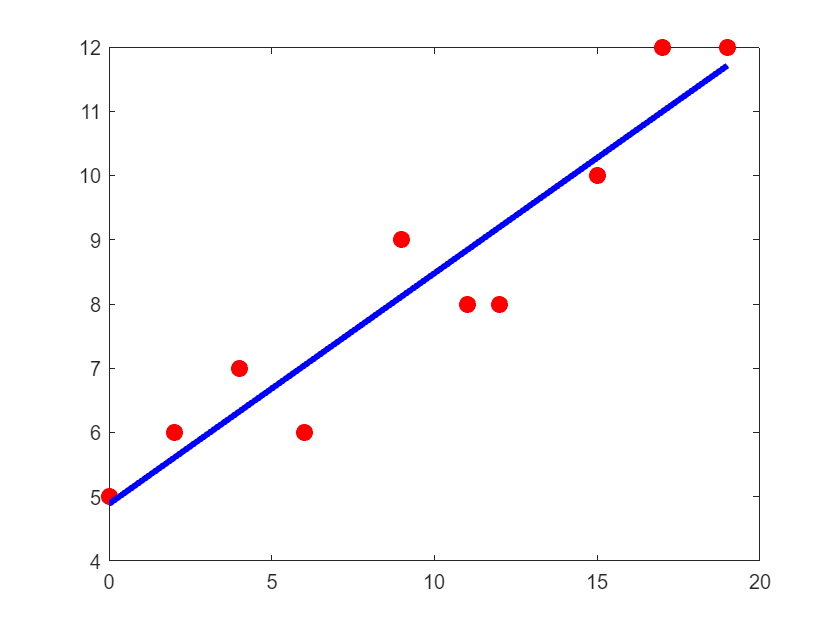


straight_line = @(x) x*slope+intercept;
x_val = linspace(0,19);
y_val = straight_line(x_val);

plot(x,y,'or','Markersize',8,'Markerfacecolor','r')
hold on
plot(x_val,y_val,'b','Linewidth',3)
hold off

2

format long
r = (n*xy_summation-x_summation*y_summation)/(sqrt(n*xSqu_summation-x_summation^2)*sqrt(n*ySqu_summation-y_summation^2))

r =    0.944925873445959


3

a = polyfit(x,y,1)

a =    0.359145527369826   4.888117489986647


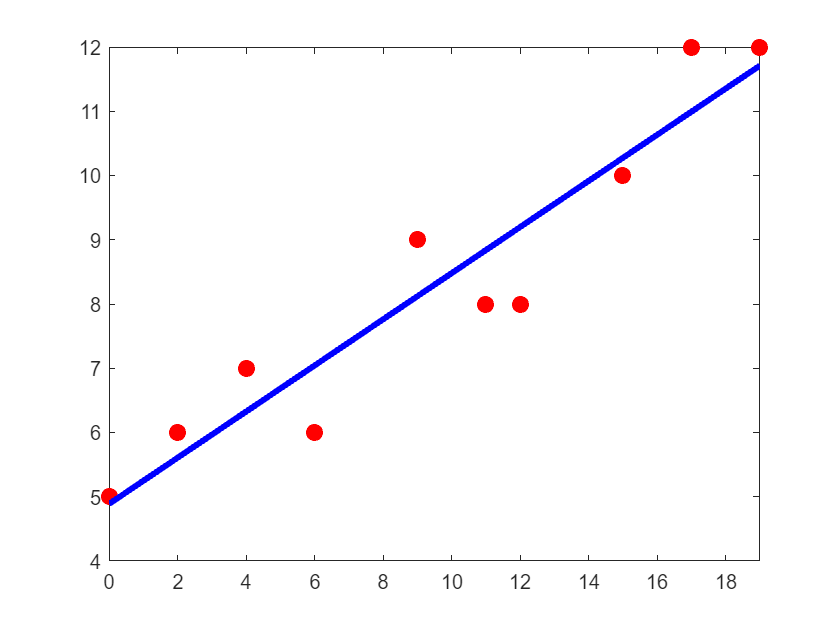

plot(x,y,'or','Markersize',8,'Markerfacecolor','r')
hold on
X = linspace(0,19);
Y=polyval(a,X);
plot(X,Y,'b','Linewidth',3)
xlim([0,19])
hold off

4 Nitrogen has a molar mass of 28.02 g/mol and atomic mass of 14.01

T=[-40 0 40 80 120 160];
p = [6900 8100 9350 10500 11700 12800];
b = polyfit(T,p,1)

b = 1.0e+03 *

   0.029607142857143   8.115238095238096


new_T = linspace(-40,160);
new_p = polyval(b,new_T);
R = (2*14.006747/100)*10^3*0.029607142857143

R =    8.293995187857181


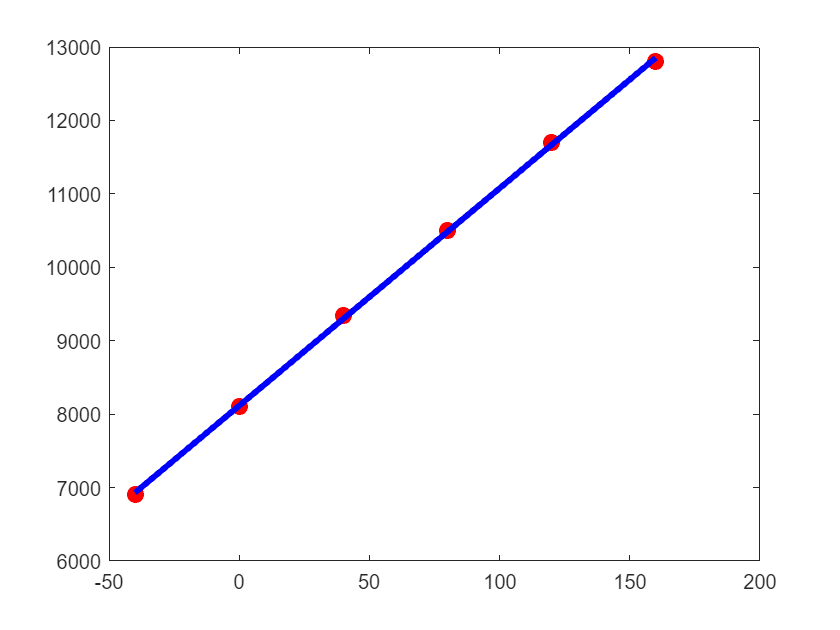


plot(T,p,'or','Markersize',8,'Markerfacecolor','r')
hold on
plot(new_T,new_p,'b','Linewidth',3)
hold off

5 find correlation coffiecient?????

x5 = [0.1 0.2 0.4 0.6 0.9 1.3 1.5 1.7 1.8];
y5 = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18];

log_val = log_func5(x5,y5)

log_val =    2.014903020542265   1.832581463748310   1.287854288306638   0.733969175080201  -0.057158413839949  -0.860201265223111  -1.455287232606842  -1.803593926875058  -2.302585092994046


b5 = polyfit(x5,log_val,1)

b5 =   -2.473308765704636   2.268178502736422


expo_fun=@(x) 9.661786.*x.*exp(-2.4733*x);


plot(x5,y5,'or','Markersize',8,'Markerfacecolor','r')
hold on
fplot(expo_fun,[0.1 2])
disp('equation: 9.661786.*x.*exp(-2.4733*x)')

equation: 9.661786.*x.*exp(-2.4733*x)


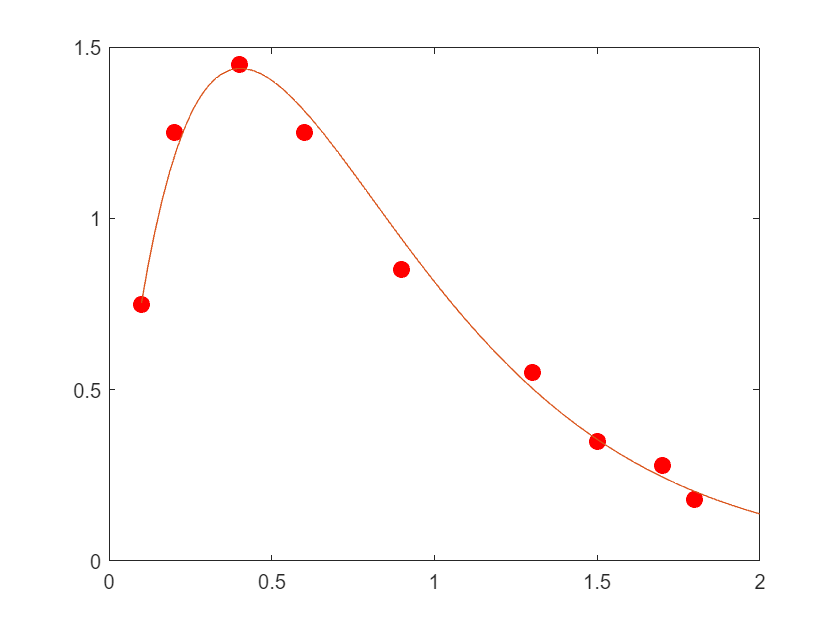

hold off

6

mass = [0.16 0.3 2 45 70 400];
Metabolism = [0.97 1.45 4.8 50 82 270];
plot(mass,Metabolism,'or','Markersize',8,'Markerfacecolor','r')
b6 = polyfit(mass,Metabolism,1)

b6 =    0.659906875438174  11.290764705960449


X6 = linspace(0,400);
Y6=polyval(b6,X6);
hold on
plot(X6,Y6,'b','Linewidth',3)

log_xval = log_base10(mass);
log_yval = log_base10(Metabolism);
log_xval_squared = log_xval.^2;
log_yval_squared = log_yval.^2; %not used
log_x_y = log_xval.*log_yval;
m6 = (6*sum(log_x_y)-sum(log_xval)*sum(log_yval))/(6*sum(log_xval_squared)-(sum(log_xval))^2)

m6 =    0.726563798967552


log_intercept6 = (sum(log_yval)-m6*sum(log_xval))/6;
real_intercept6 = 10^log_intercept6

real_intercept6 =    3.389306511176279


y6=@(x) real_intercept6*x.^m6;
disp('equation = 3.389306511176279*x.^0.726563798967552')

equation = 3.389306511176279*x.^0.726563798967552


tiger_metabolism = y6(200)

tiger_metabolism =      1.592047206771982e+02


result = [num2str(tiger_metabolism) ' watt']

result = '159.2047 watt'

disp(result)

159.2047 watt


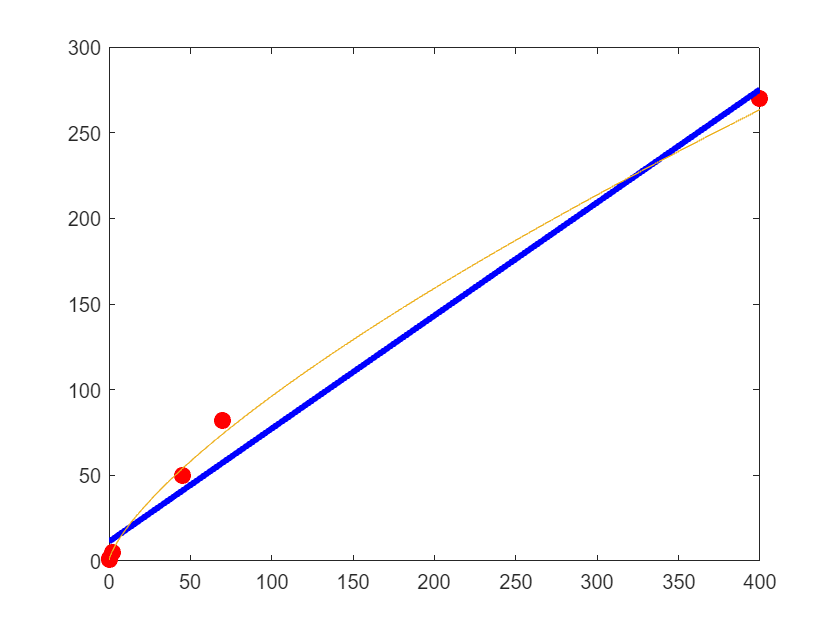

fplot(y6,[0 400])
hold off

8

distance = [2.4 1.5 2.4 1.8 1.8 2.9 1.2 3 1.2]

distance =    2.400000000000000   1.500000000000000   2.400000000000000   1.800000000000000   1.800000000000000   2.900000000000000   1.200000000000000   3.000000000000000   1.200000000000000


width = [2.9 2.1 2.3 2.1 1.8 2.7 1.5 2.9 1.5]

width =    2.900000000000000   2.100000000000000   2.300000000000000   2.100000000000000   1.800000000000000   2.700000000000000   1.500000000000000   2.900000000000000   1.500000000000000


plot(distance,width,'or','Markersize',8,'Markerfacecolor','r')
hold on
x8_sum = sum(distance)

x8_sum =   18.199999999999999


y8_sum = sum(width)

y8_sum =   19.800000000000001


x8_squared_sum = sum(distance.^2)

x8_squared_sum =   40.539999999999999


x8y8_sum = sum(distance.*width) %NOT x8_sum*y8_sum!!!!!

x8y8_sum =   42.779999999999987


n8=length(distance)

n8 =      9



m8=(n8*x8y8_sum-x8_sum*y8_sum)/(n8*x8_squared_sum-x8_sum^2)

m8 =    0.733491969066026


y_intercept8 = (y8_sum-m8*x8_sum)/n8

y_intercept8 =    0.716716240333147


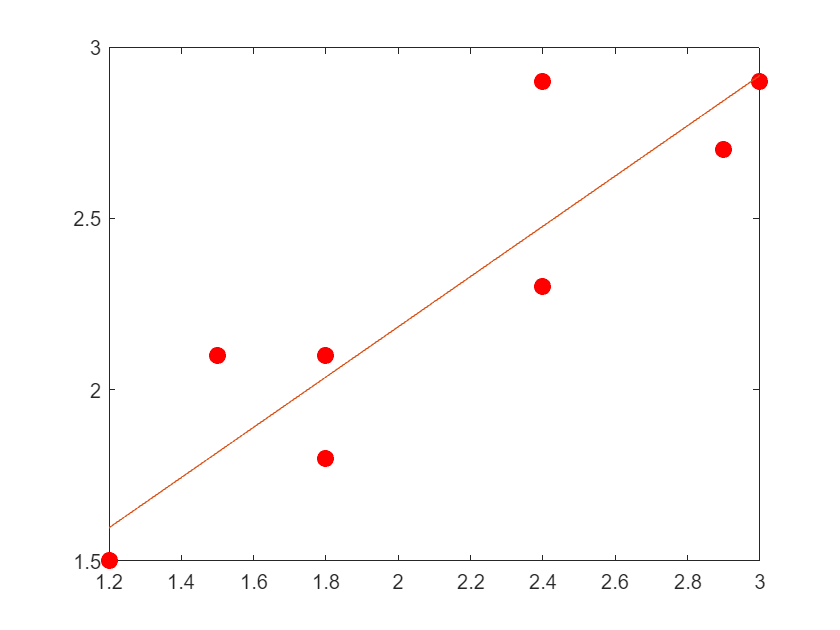


y8 = @(x) y_intercept8+m8*x;
fplot(y8, [1.2 3])
hold off

result9 = [num2str(y8(1.8)) ' m'];
disp(result9)

2.037 m


9?????

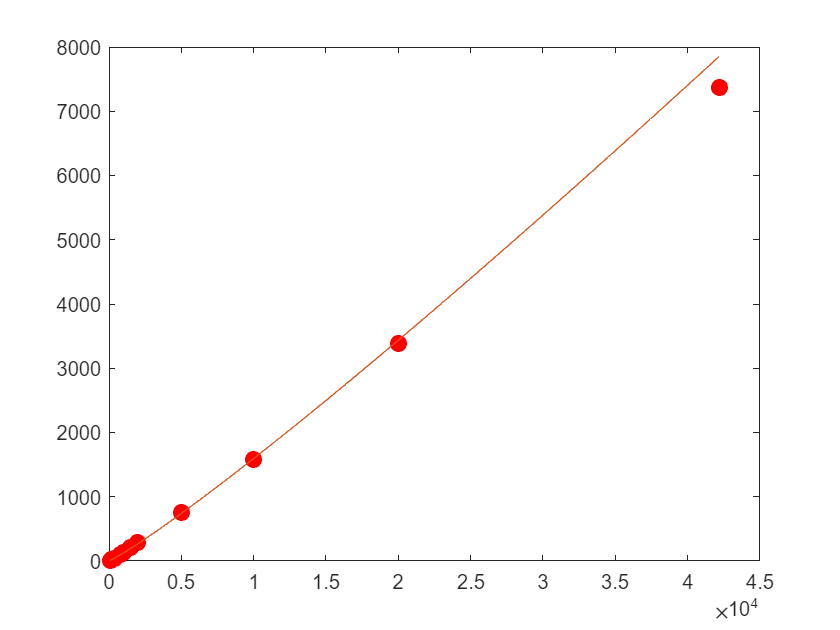

format long
event_running = [100 200 400 800 1000 1500 2000 5000 10000 20000 42195];
men_time = [9.58 19.19 43.18 100.90 131.96 206.00 284.79 757.4 1577.53 3386 7377];
women_time = [10.49 21.34 47.6 113.28 148.98 230.07 325.35 851.15 1771.78 3926.6 8125];
plot(event_running,men_time,'or','Markersize',8,'Markerfacecolor','r')
hold on
%power equation
log_xval9 = log_base10(event_running);
log_yval9_men = log_base10(men_time);
log_xval_squared9 = log_xval9.^2;
log_x_y9_men = log_xval9.*log_yval9_men;
n9 = length(event_running);

slope9_men = (n9*sum(log_x_y9_men)-sum(log_xval9)*sum(log_yval9_men))/(n9*sum(log_xval_squared9)-(sum(log_xval9))^2);
log_intercept9_men = (sum(log_yval9_men)-slope9_men*sum(log_xval9))/n9;
y9=@(x) (10^log_intercept9_men)*x.^slope9_men;
fplot(y9,[100 42195])
hold off

y9(21097.5)

ans =      3.645987272687127e+03


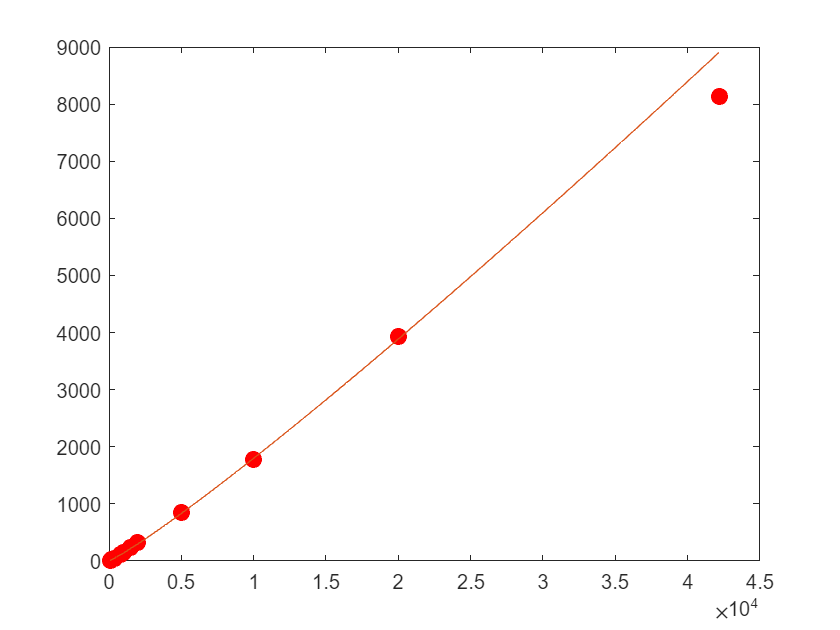


log_yval9_women = log_base10(women_time);
log_xval_squared9 = log_xval9.^2;
log_x_y9_women = log_xval9.*log_yval9_women;

slope9_women = (n9*sum(log_x_y9_women)-sum(log_xval9)*sum(log_yval9_women))/(n9*sum(log_xval_squared9)-(sum(log_xval9))^2);
log_intercept9_women = (sum(log_yval9_women)-slope9_women*sum(log_xval9))/n9;
y92=@(x) (10^log_intercept9_women)*x.^slope9_women;
plot(event_running,women_time,'or','Markersize',8,'Markerfacecolor','r')
hold on
fplot(y92,[100 42195])
hold off

y92(21097.5)

ans =      4.124413268473044e+03


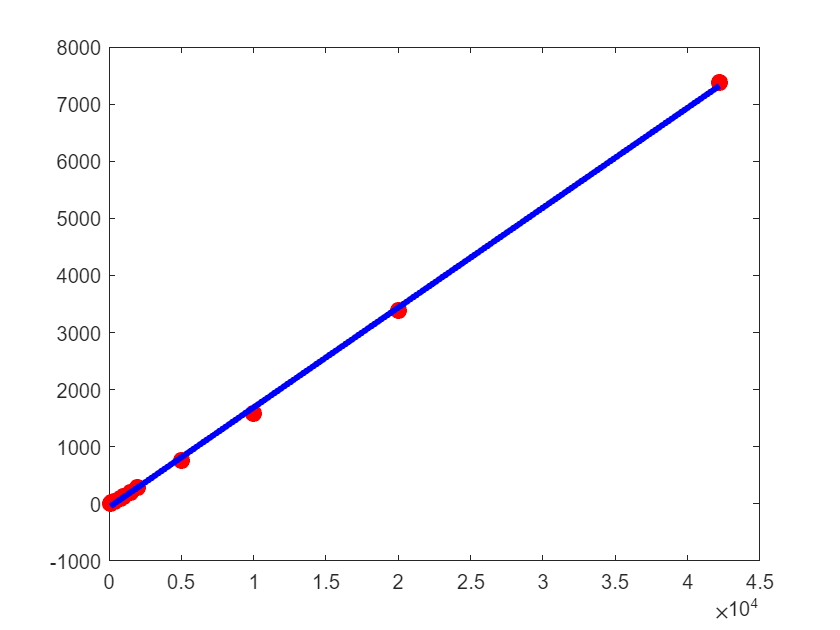



%polyfit
a = polyfit(event_running,men_time,1);
plot(event_running,men_time,'or','Markersize',8,'Markerfacecolor','r')
hold on
X = linspace(100,42195);
Y=polyval(a,X);
plot(X,Y,'b','Linewidth',3)
hold off

21097.5*a(1)+a(2)

ans =      3.630240083692036e+03


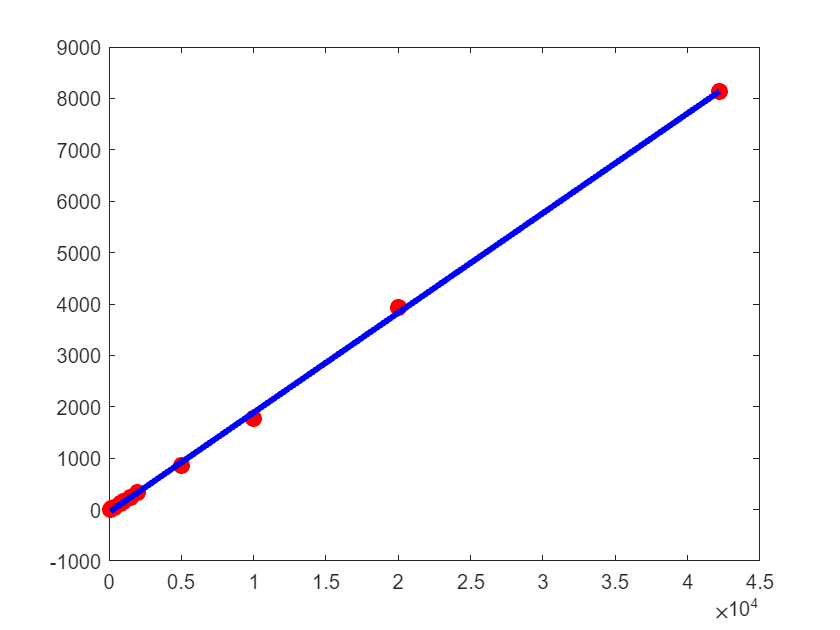


a = polyfit(event_running,women_time,1);
plot(event_running,women_time,'or','Markersize',8,'Markerfacecolor','r')
hold on
X = linspace(100,42195);
Y=polyval(a,X);
plot(X,Y,'b','Linewidth',3)
hold off

21097.5*a(1)+a(2)

ans =      4.041860162327732e+03


functions

function [l,L] = least_square(sumx,sumy,sumxy,sumx_square,n)
    m = (n*sumxy-sumx*sumy)/(n*sumx_square-sumx^2);
    b= (sumy-m*sumx)/n;
    l = m;
    L = b;
end


function l = Summation(x)
    x_sum = 0;
    for i=1:length(x)
        x_sum = x_sum+x(i);
    end
    l=x_sum;
end


function l = xySummation(x,y)
    xy_sum = 0;
    for i=1:length(x)
        xy_sum = xy_sum+x(i)*y(i);
    end
    l=xy_sum;
end
    

function l = xsquSummation(x)
    x_sum = 0;
    for i=1:length(x)
        x_sum = x_sum+x(i)^2;
    end
    l = x_sum;
end


function result = log_func5(x,y)
    result = [];
    for i=1:length(x)
        result(end+1)=log(y(i)/x(i));
    end
end


function a=log_base10(vec)
    a=[];
    for i=1:length(vec)
        a(end+1)=log10(vec(i));
    end
end

